# **Análise e Modelagem de Sistemas Dinâmicos - 2023/2**

## Nome: Thiago Felippe Neitzke Lahass

## Data limite para entrega: 27/11/2023

### A entrega deverá ser feita pelo Google ClassRoom

# Trabalho 3 - Resposta no Tempo, Estabilidade e Sistemas Discretos

I = 10;         % Seu número I
init_t3(I);     % Define as variaveis do modelo 1
datetime('now')

ans = datetime
   27-Nov-2023 21:10:02


**Funções úteis do Matlab:** tf, tfdata, step, RespConfig, minreal, figure, plot, hold, grid, stairs, title, xlabel, ylabel, legend, sprintf, fprintf, ss, d2c, roots, sort, real, imag, abs, sqrt, poly, length, feedback, initial, tf2ss, cart2pol, eig, vpa, eval.

## Análise da Resposta no Tempo Contínuo

A Função de Transferência baixo foi designada em função do seu valor de I.

G

G =
 
                          4000
  -----------------------------------------------------
  s^4 + 546.7 s^3 + 7.827e04 s^2 + 1.915e06 s + 2.56e07
 
Continuous-time transfer function.
Model Properties


### 1.1 Plote a resposta ao degrau de $G\left(s\right)$ para um degrau de amplitude $U$.

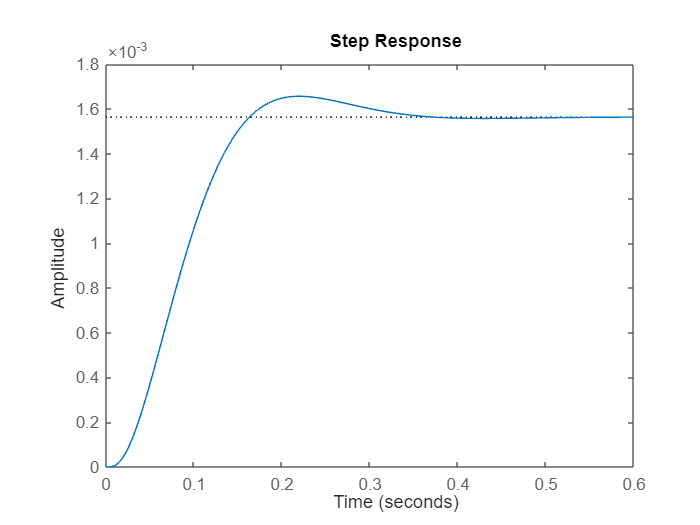

% Simulando a resposta de G(s) ao degrau U 
step(U * G);

### 1.2 Encontre a função $Q\left(s\right)$ de 1ª ou de 2ª ordem (conforme o caso), cuja resposta ao degrau se aproxime a resposta ao degrau de $G\left(s\right)$.

Como há um sobreimpulso claro na resposta de $G\left(s\right)$ ao degrau, temos que $Q\left(s\right)$ deve ser de segunda ordem. Logo, analizando a forma padrão de um sistema de segunda ordem, temos:

$G\left(s\right)=K\frac{\omega_n^2 }{s^2 +2\zeta \omega_n s+\omega_n }$,

onde:

$\omega_n$ é denominada a frequência natural do sistema, e

$\zeta$ é denominado o fator de amortecimento do sistema.

Como o sistema é subamortecido (0 < $\zeta$ < 1), então podemos obter $\zeta$ e $\omega_n$ a partir dos valores de máximo sobreimpulso $M_p$, e tempo de pico $t_p$, a partir do seguinte:

$\zeta =\frac{-\;\ln \left(M_p \right)}{\sqrt{\pi^2 +\ln^2 \left(M_p \right)}}$ e $\omega_n =\frac{\pi }{t_p \sqrt{1-\zeta^2 }}$, onde $M_p =\frac{y\left(t_p \right)-y\left(\infty \right)}{y\left(\infty \right)}$.

Como conseguimos aferir os valores de $K$, $t_p$, $y\left(t_p \right)$ e $y\left(\infty \right)$, conseguimos obter todos os parâmetros necessários para representar nossa FT de segunda ordem.

Fazendo todo o procedimento de obteção e calculo dos coeficientes, temos:

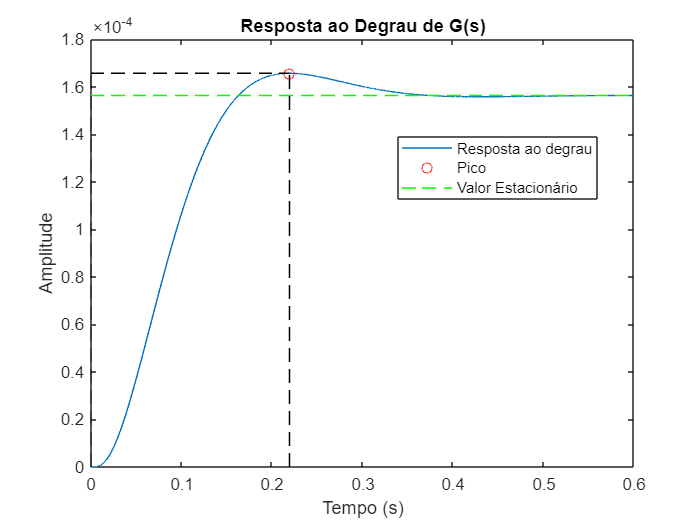

% Simulando a resposta de G(s) ao degrau 
time_span = linspace(0, 0.6, 10000);
[y1, t] = step(G, time_span);

% Encontrando os picos da resposta ao degrau
[peaks, peak_times] = findpeaks(y1, t);

% Encontrando o valor máximo (magnitude do pico) e o instante (tp) em que ocorre
[max_peak, max_peak_index] = max(peaks);
tp = peak_times(max_peak_index);

% Calculando o valor Estacionário
final_value = y1(end);

% Plotando a resposta ao degrau com o pico destacado
figure;
plot(t, y1, tp, max_peak, 'ro');
hold on;

% Adicionando a linha tracejada indicando o valor estacionário
line([time_span(1), time_span(end)], [final_value, final_value], 'Color', 'g', 'LineStyle', '--');

% Adicionando linhas perpendiculares aos eixos no ponto de pico
plot([tp, tp], [0, max_peak], 'k--');           % Linha vertical até o pico
plot([0, tp], [max_peak, max_peak], 'k--');     % Linha horizontal até o tempo do pico
plot([tp, tp], [0, 0], 'k--');                  % Linha vertical até o eixo x
plot([0, 0], [0, max_peak], 'k--');             % Linha horizontal até o eixo y

title('Resposta ao Degrau de G(s)');
xlabel('Tempo (s)');
ylabel('Amplitude');

% Posicionando a legenda abaixo do gráfico para não atrapalhar visualização
legend('Resposta ao degrau', 'Pico', 'Valor Estacionário', 'Location','best');

hold off;


fprintf('Valor máximo (magnitude do pico): %.10f\n', max_peak);

Valor máximo (magnitude do pico): 0.0001655872


fprintf('Instante do pico: %.10f segundos\n', tp);

Instante do pico: 0.2193219322 segundos


fprintf('Valor final (Estacionário): %.10f\n', final_value);

Valor final (Estacionário): 0.0001562680


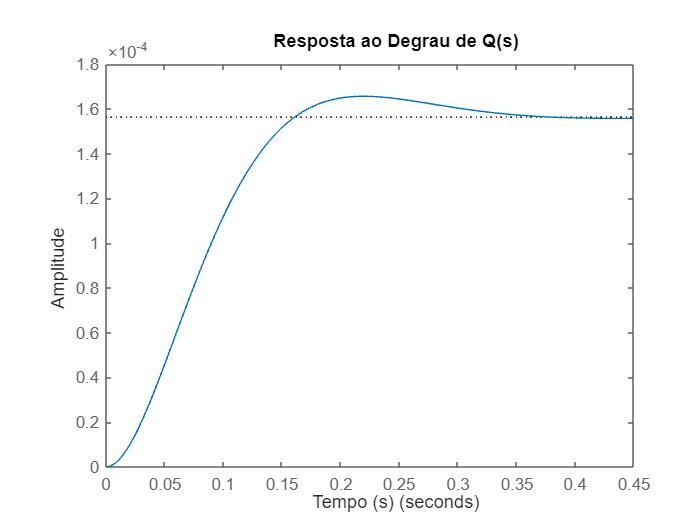

% Encontrando os valores das constantes da fórmula padrão
K = final_value;
Mp = (max_peak - final_value)/final_value;
zeta = -log(Mp)/sqrt(pi^2 + log(Mp)^2);
wn = pi/(tp*sqrt(1 - zeta^2));
% Criando a função de transferência Q(s),  a partir da forma padrão G(s) = (K * wn^2) / (s^2 + 2*zeta*wn*s + wn^2)
numerator = K * wn^2;
denominator = [1, 2 * zeta * wn, wn^2];

Q = tf(numerator, denominator);

% Simulando a resposta de Q(s) ao degrau
step(Q);
hold on;
title('Resposta ao Degrau de Q(s)');
xlabel('Tempo (s)');
ylabel('Amplitude');
hold off;

### 1.3 Compare, no mesmo gráfico, a resposta ao degrau de $Q\left(s\right)$ com a resposta ao degrau de $G\left(s\right)$ para um degrau de amplitude $U$. Explique a resposta.

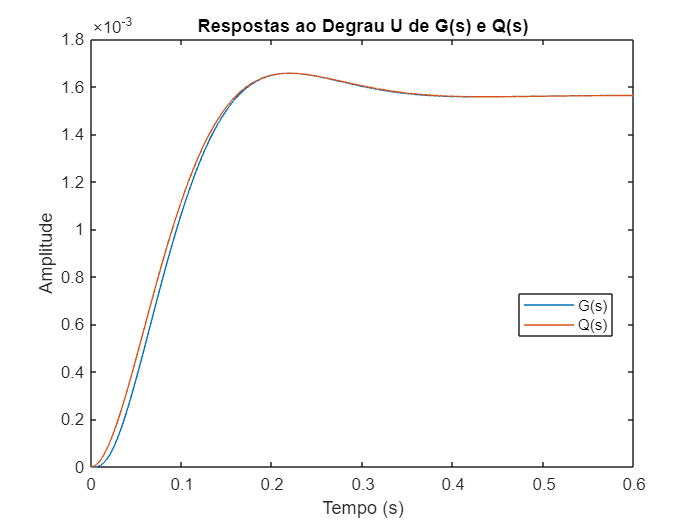

% Simulando a resposta de G(s) ao degrau U
[y2, ~] = step(U * G, time_span);

% Simulando a resposta de Q(s) ao degrau U
[y3, t] = step(U * Q, time_span);

% Plotar os gráficos de G(s) e Q(s) em um único gráfico
plot(t, y2);
hold on;
plot(t, y3);
hold off;

title('Respostas ao Degrau U de G(s) e Q(s)');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('G(s)', 'Q(s)', 'Location','best');

Vemos através dos gráficos plotados que os valores de pico e os valores estacionários de ambas funções de transferêcia são iguais. Além disso, é notável que a FT de segunda ordem $Q\left(s\right)$ começa a "subir" (responder) um pouco antes que $G\left(s\right)$, enquanto que a FT $G\left(s\right)$ tem um pequeno delay am relação a $Q\left(s\right)$ antes de começar a responder de forma significativa. Podemos ver a causa disso analisando os polos de $G\left(s\right)$ e $Q\left(s\right)$:

pole(G)

ans = 1.0e+02 *

  -3.2000 + 0.0000i
  -2.0000 + 0.0000i
  -0.1333 + 0.1491i
  -0.1333 - 0.1491i


pole(Q)

ans =  -12.8555 +14.3241i
 -12.8555 -14.3241i


Sabemos que, quanto mais distante os polos estiverem do eixo imaginário, mais veloz é a resposta gerada. É fácil notar que os polos de $G\left(s\right)$ estão mais próximos ao eixo imaginário do que os polos de $Q\left(s\right)$, logo são mias lentos, e portanto isso gera o resultado visto no gráfico acima.

### 1.4 A partir da equação de $Q\left(s\right)$ e de medições feitas diretamente no gráfico da resposta ao degrau de $Q\left(s\right)$, para um degrau de amplitude $U$, informe os valores de $\zeta$, $\omega_n$, $\textrm{MP}$, $t_p$, $t_r$ e $t_s \left(5%\right)$. (Mostre com *Data Tips* sempre que for possível marcar os valores no gráfico)

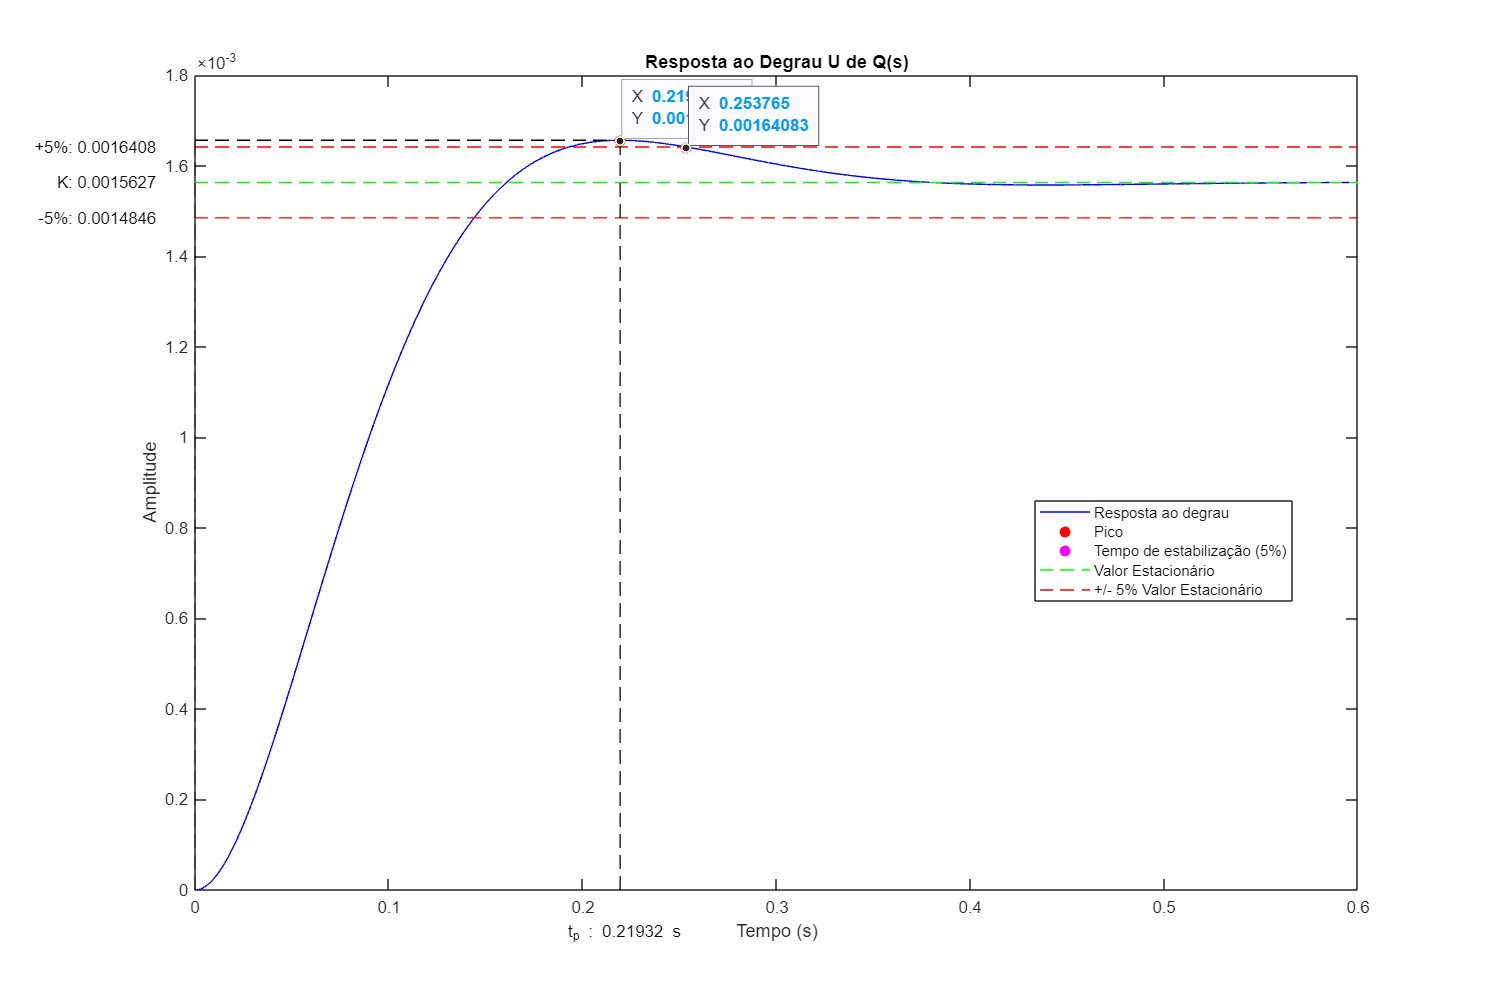

% Simulando a resposta de Q(s) ao degrau U 
[yq, t] = step(U * Q, time_span);

% Encontrando os picos da resposta ao degrau U
[peaks, peak_times] = findpeaks(yq, t);

% Encontrando o valor máximo (magnitude do pico) e o instante (tp) em que ocorre
[max_peak, max_peak_index] = max(peaks);
tp = peak_times(max_peak_index);

% Calculando o valor Estacionário
final_value = yq(end);

%Além disso, podemos calcular os valores de tr e ts5 a partir da resposta
%que obtemos para a simulação de Q(s) para o degrau U, que esta em y3.
%Assim:

% Encontrando o índice correspondente a 10% e 90% do valor final
y_10 = 0.1 * final_value;
y_90 = 0.9 * final_value;

% Encontrando os tempos correspondentes a 10% e 90%
t_10 = interp1(y3, t, y_10);
t_90 = interp1(y3, t, y_90);

% Calculando o tempo de subida
t_r = t_90 - t_10;

% Encontrando os limites de +/-5% do valor estacionário
limite_superior = final_value * 1.05;
limite_inferior = final_value * 0.95;

%além disso, para o tempo de estabilização de 5% (t_s5), temos:
indices_limite_superior = find(yq >= limite_superior);
tempos_limite_superior = t(indices_limite_superior);
t_s5 = max(tempos_limite_superior);
% Encontrando o índice correspondente ao instante t_s5
indice_t_s5 = find(t == t_s5);
% Obtendo o valor de yq no instante t_s5
yq_t_s5 = yq(indice_t_s5);

% Ajustando o tamanho da figura
figure('Position', [100, 100, 1200, 800]);  % [left, bottom, width, height]
plot(t, yq, 'b');
hold on;

% Plotando a resposta ao degrau com o pico destacado
plot(tp, max_peak, 'ro', 'MarkerFaceColor', 'r');

% Destacando o instante que atinge tempo de estabilização de 5%
plot(t_s5, yq_t_s5, 'mo', 'MarkerFaceColor', 'm');

% Adicionando a linha tracejada indicando o valor estacionário
line([time_span(1), time_span(end)], [final_value, final_value], 'Color', 'g', 'LineStyle', '--');

% Adicionando linhas tracejadas indicando os limites de +/-5% do valor estacionário
line([time_span(1), time_span(end)], [limite_superior, limite_superior], 'Color', 'r', 'LineStyle', '--');
line([time_span(1), time_span(end)], [limite_inferior, limite_inferior], 'Color', 'r', 'LineStyle', '--');

% Adicionando linhas perpendiculares aos eixos no ponto de pico
plot([tp, tp], [0, max_peak], 'k--');           % Linha vertical até o pico
plot([0, tp], [max_peak, max_peak], 'k--');     % Linha horizontal até o tempo do pico
plot([tp, tp], [0, 0], 'k--');                  % Linha vertical até o eixo x
plot([0, 0], [0, max_peak], 'k--');             % Linha horizontal até o eixo y

% Adicionando textos aos pontos relevantes
% text(tp, max_peak + 0.00001, [' y( t_p ): ' num2str(max_peak)], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% text(t_s5, max_peak + 0.00001, [' t_s5: ' num2str(t_s5)], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
text(tp, -0.00007, [' t_p : ' num2str(tp) ' s'], 'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
text(-0.02, final_value, [' K: ' num2str(final_value)], 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
text(-0.02, limite_superior, [' +5%: ' num2str(limite_superior)], 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
text(-0.02, limite_inferior, [' -5%: ' num2str(limite_inferior)], 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');

title('Resposta ao Degrau U de Q(s)');
xlabel('Tempo (s)');
ylabel('Amplitude');

lgd = legend('Resposta ao degrau', 'Pico', 'Tempo de estabilização (5%)', 'Valor Estacionário', '+/- 5% Valor Estacionário','Location','best');

 
ax = gca;
chart = ax.Children(7);
datatip(chart,0.2193,0.001656);
TempoDeEstabilizao5 = findobj(gcf, "DisplayName", "Tempo de estabilização (5%)");
datatip(TempoDeEstabilizao5,0.2538, 0.001641);
hold off;



% Os valores de zeta, w_n, MP, tp já foram calculados no item 1.2, sendo eles:
fprintf('zeta: %f\n', zeta)

zeta: 0.667926


$\zeta =0\ldotp 6679626$. 

fprintf('wn: %f rad/s\n', wn)

wn: 19.246950 rad/s


$\omega_n =19\ldotp 246950\frac{\textrm{rad}}{s}$.

fprintf('MP: %f\n', Mp)

MP: 0.059636


$M_p =0\ldotp 059636$.

fprintf('tp: %f\n', tp)

tp: 0.219322


$t_p =0\ldotp 219322\;s$.

fprintf('tr: %f s\n', t_r)

tr: 0.105575 s


$t_r =0\ldotp 105575\;s$.

fprintf('t_s5: %f s\n', t_s5)

t_s5: 0.253765 s


E por fim, $t_{\textrm{s5}} =0\ldotp 253765\;s$.

### 1.5 Feche a malha do processo $G\left(s\right)$ com uma realimentação de ganho $K$. Obtenha a faixa de valores de $K$ em que o sistema é estável.

Fechando a malha com uma realimentação de ganho $K$ obtemos a nova função de transferência:

G

G =
 
                          4000
  -----------------------------------------------------
  s^4 + 546.7 s^3 + 7.827e04 s^2 + 1.915e06 s + 2.56e07
 
Continuous-time transfer function.
Model Properties



$$G_k \left(s\right)=\frac{G\left(s\right)}{1+K\;G\left(s\right)}$$



$$G_k \left(s\right)=\frac{4000}{s^4 +546\ldotp 7\;s^3 +7\ldotp 827\textrm{e04}\;s^2 +1\ldotp 915\textrm{e06}\;s+2\ldotp 56\textrm{e07}+4000\;K}$$


Para que possamos aplicar a Tabela de Routh é necessário que:

$2\ldotp 56\textrm{e07}+4000\;K>0$.

syms k;
cell2mat(G.Denominator)

ans = 1.0e+07 *

    0.0000    0.0001    0.0078    0.1915    2.5600


solve(2.5600*10^7 + 4000*k > 0)

$$ans = -6399$$


$$\Rightarrow K>-6399$$


Motando a tabela, temos:

$s^4$ |  $1$                                                   $7\ldotp 827\textrm{e04}$                              $2\ldotp 56\textrm{e07}+4000\;K$  

$s^3$ |  $546\ldotp 7$                                            $1\ldotp 915\textrm{e06}$                              $0$

----------------------------------------------------------------------------------------------------

$s^2$ |   $74767\ldotp 16$                                      $2\ldotp 56\textrm{e07}+4000\;K$                $0$

$s^1$ |   $\frac{1\ldotp 292\textrm{e11}-2186800\;K}{74767\ldotp 16}$                 $0$                                           $0$

$s^0$ |   $2\ldotp 56\textrm{e07}+4000\;K$                         $0$                                           $0$

Portanto, necessitamos que os elementos da primeira coluna seja todos maiores que zero para o sistema ser estável. Assim, para ser estável precisamos que:

$\frac{1\ldotp 292\textrm{e11}-2186800\;K}{74767\ldotp 16}>0\Rightarrow 1\ldotp 292\textrm{e11}-2186800\;K>0$.

solve(1.292*10^11 - 2186800*k > 0)

$$ans = \frac{322994533}{5467}$$

$\Rightarrow K<59081$.

$2\ldotp 57\textrm{e07}+4000\;K>0\Rightarrow K>-6399$. 

Logo, fazendo a interseção dos valores de $K$, temos que o sistema é estável para $-6399<K<59081$. Podem haver pequenas diferenças entre os números vistos e os que são de fato devido às aproximações feitas durante os cálculos.

## Análise da Resposta no Tempo Discreto

A Função de Transferência baixo foi designada em função do seu valor de I.

Dz

Dz =
 
  2.038e-05 z^2 + 4.076e-05 z + 2.038e-05
  ---------------------------------------
          z^2 - 0.7826 z + 0.3043
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


### 2.1 Obtenha o modelo equivalente contínuo $D_t \left(s\right)$ de $D\left(z\right)$ usando a transformação bilinear para $T_s =50\left\lbrack \textrm{ms}\right\rbrack$.

Para obter o equivalente contínuo de um sistema discreto usando a transformação bilinear, podemos usar a seguinte fórmula de mapeamento:

$z=1+T_s \;s$, onde $T_s$ é o tempo de amostragem discreto ($50\;\textrm{ms}$) no nosso caso.

Porém, com a disposição do matlab podemos utilizar simplesmente a função "d2c" na qual convertemos uma função de transferência no tempo discreto para tempo contínuo especificando o método de conversão.

% Convertendo Dz pro tempo continuo (Dt) pelo método de 'tustin'
Dt = d2c(Dz,'tustin')

Dt =
 
        0.0625
  -------------------
  s^2 + 26.67 s + 400
 
Continuous-time transfer function.
Model Properties


### 2.2 Obtenha o modelo equivalente contínuo $D_{\textrm{zoh}} \left(s\right)$ de $D\left(z\right)$ usando ZOH para $T_s =50\left\lbrack \textrm{ms}\right\rbrack$.

Para obter a equivalencia entre um sistema contínuo e um sistema discreto usando a transformação ZOH, podemos usar a seguinte fórmula de mapeamento:

$P_d \left(z\right)=\left(1-z^{-1} \right)Z\left\lbrace L^{-1} {\left\lbrack P\left(s\right)\frac{1}{s}\right\rbrack }_{t={\textrm{kT}}_s } \right\rbrace$.

Porém, com a disposição do matlab podemos utilizar simplesmente a função "d2c" na qual convertemos uma função de transferência discreto para contínua especificando o método de conversão.    

% Convertendo Dz pro tempo continuo (Dzoh) pelo método de 'zoh'
Dzoh = d2c(Dz,'zoh')

Dzoh =
 
  2.038e-05 s^2 + 0.001055 s + 0.06036
  ------------------------------------
         s^2 + 23.79 s + 386.3
 
Continuous-time transfer function.
Model Properties


### 2.3 Compare a resposta ao degrau unitário de $D_z \left(z\right)$, $D_{\textrm{zoh}} \left(s\right)$ e $D_t \left(s\right)$. Explique o resultado.

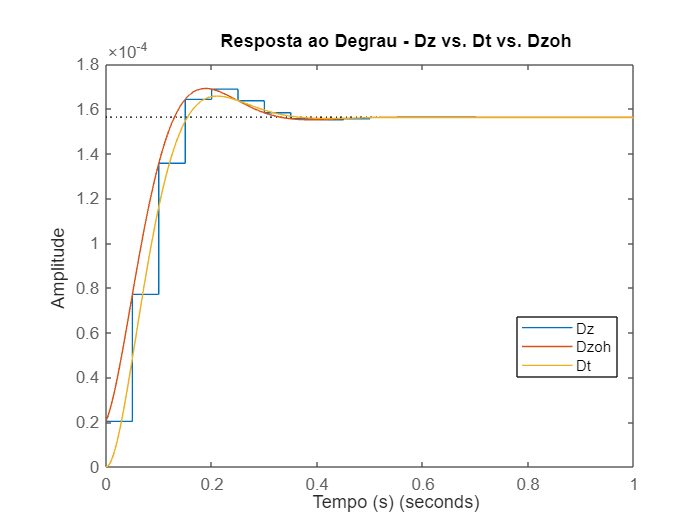

figure;
step(Dz, Dzoh, Dt);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Resposta ao Degrau - Dz vs. Dt vs. Dzoh');
legend('show', 'Location', 'best');

No gráfico, o método ZOH preserva exatamente a resposta ao degrau do sistema discreto, enquanto o método Tustin, sendo uma aproximação, apresenta pequenas diferenças.

### 2.4 Obtenha as matrizes do modelo no EE de $D_z \left(z\right)$.

Podemos obter as matrizes de modelo em EE de $D_z \left(z\right)$ a partir da função disponível no matlab 'tf2ss', que nos permite passar os coeficientes do numerador e do denominador da função de transferência e nos retorna as matrizes em EE do modelo.

% Obter os coeficientes do numerador e denominador
numerator= cell2mat(Dz.Numerator)

numerator = 1.0e-04 *

    0.2038    0.4076    0.2038


denominator = cell2mat(Dz.Denominator)

denominator =     1.0000   -0.7826    0.3043



[A,B,C,D] = tf2ss(numerator, denominator)

A =     0.7826   -0.3043
    1.0000         0


B =      1
     0


C = 1.0e-04 *

    0.5671    0.1418


D = 2.0380e-05

### 2.5 Obtenha a matrix de transição de estados $\Phi[k] = A^k$ e use-a para obter a saída $y[k]$ do sistema para $\vec{q}_0$ com todos os elementos iguais a 1. Compare a resposta obtida com a produzida pela função "initial" do MATLAB. Considere $T_s =50\left\lbrack \textrm{ms}\right\rbrack$ e apresente o gráfico com tempo até três segundos.

Temos a matriz A:

A

A =     0.7826   -0.3043
    1.0000         0


Assim podemos calcular $A^k$ através de Cayley Hamilton. Como a matriz $A$ é 2x2, então sabemos que:

$A^k =p_o \left(k\right)+p_1 \left(k\right)A$.

Para encontrar $p_0 \left(k\right)$ e $p_1 \left(k\right)$ precisamos determinar os autovalores da matriz $A$:

lambda = eig(A)

lambda =    0.3913 + 0.3889i
   0.3913 - 0.3889i


Logo $\lambda_1 =0\ldotp 3913+0\ldotp 3889j$ e $\lambda_2 =0\ldotp 3913+0\ldotp 3889j$. Podemos passar esses valores para a forma polar:

mod1 = sqrt( real(lambda(1,1))^2 + imag(lambda(1,1))^2)

mod1 = 0.5517

ang1 = atan(imag(lambda(1,1)) / real(lambda(1,1)))

ang1 = 0.7823

mod2 = sqrt( real(lambda(2,1))^2 + imag(lambda(2,1))^2)

mod2 = 0.5517

ang2 = atan(imag(lambda(2,1)) / real(lambda(2,1)))

ang2 = -0.7823


$$\lambda_1 =0\ldotp 3913+0\ldotp 3889j=0\ldotp 5517e^{0\ldotp 7823j}$$
 


$$\lambda_2 =0\ldotp 3913+0\ldotp 3889j=0\ldotp 5517e^{-0\ldotp 7823j}$$


Assim, podemos determinar $p_o \left(k\right)$ e $p_1 \left(k\right)$:


$$\[
\begin{cases}
  (0.5517e^{0.7823j})^k = p_0(k) + p_1(k)(0.3913 + 0.3889j) \\
  (0.5517e^{-0.7823j})^k = p_0(k) + p_1(k)(0.3913 - 0.3889j) \\
\end{cases}
\]

$$


Subtraindo as equações:

$\frac{0\ldotp {5517}^k \;\left(e^{0\ldotp 7823j\;k} -e^{-0\ldotp 7823j\;k} \right)}{2j}=0\ldotp 3889\;p_1 \left(k\right)\Rightarrow p_1 \left(k\right)=\frac{0\ldotp {5517}^k \cdot \textrm{sen}\left(0\ldotp 7823\;k\right)}{0\ldotp 3889}$;

já somando as equações, temos:

$\frac{0\ldotp {5517}^k \;\left(e^{0\ldotp 7823j\;k} +e^{-0\ldotp 7823j\;k} \right)}{2}=p_0 \left(k\right)+0\ldotp 3913p_1 \left(k\right)\Rightarrow p_0 \left(k\right)=0\ldotp {5517}^k \cdot \cos \left(0\ldotp 7823\;k\right)-0\ldotp 3913p_1 \left(k\right)$.

Agora basta substituir $p_0 \left(k\right)$, $p_1 \left(k\right)$ e $A$ em $A^k =p_o \left(k\right)+p_1 \left(k\right)A$, que teremos a matriz de transição de estados $A^k$.

Finalmente, para encontrar a saída natural$y\left(k\right)$ para um condição inicial $\vec{q_0 }$, podemos utilizar a seguinte forma:

$y\left(k\right)=\left\lbrack C_d \right\rbrack \;A^k \;\vec{q_0 }$, onde $\left\lbrack C_d \right\rbrack =\left\lbrack C\right\rbrack$ e pelo enunciado $\vec{q_0 } =\left\lbrack 1,1\right\rbrack$.

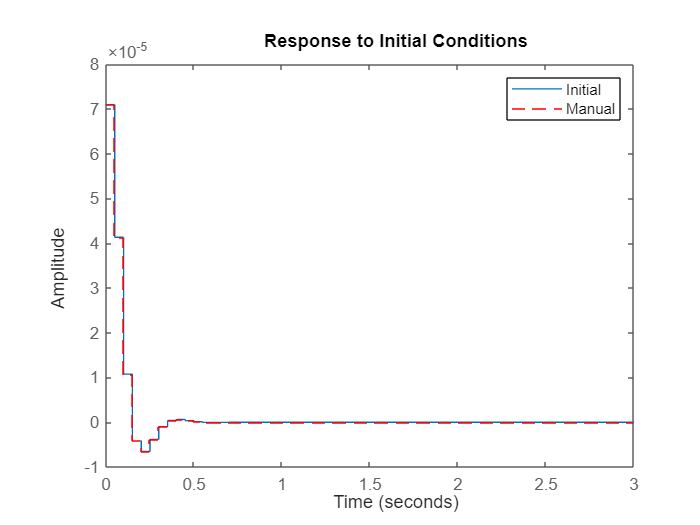

Ts = 0.05;
k_values = (0:1:3/Ts); % k deve ser inteiro, 3 segundos equivale a 60 amostras na frequencia dada no enunciado (Ts = 50 ms)
vk = length(k_values);
yk = vk * 0;
q0 = [1;1];

for k = k_values
    p1 = (0.5517^k * sin(0.7823 * k)) / 0.3889;
    p0 = 0.5517^k * cos(0.7823 * k) - 0.3913 * p1;
    Ak = p0 * eye(2) + p1 * A;
    yk(k+1) = C * Ak * q0;
end

sys = ss(A,B,C,D, Ts);
figure;
initial(sys,q0,3);
hold on;
stairs(k_values*Ts, yk, '--r');
legend('Initial', 'Manual');
hold off;

Como no enunciado pede tempo com até 3 segundos ele está apresentado acima, porém, como a função se estabiliza logo no começo (em aproxidamente 0.6 segundos já está quase totalmente estabilizado), podemos plotar até apenas 1 segundo para uma melhor visualização e análise dos resultados:

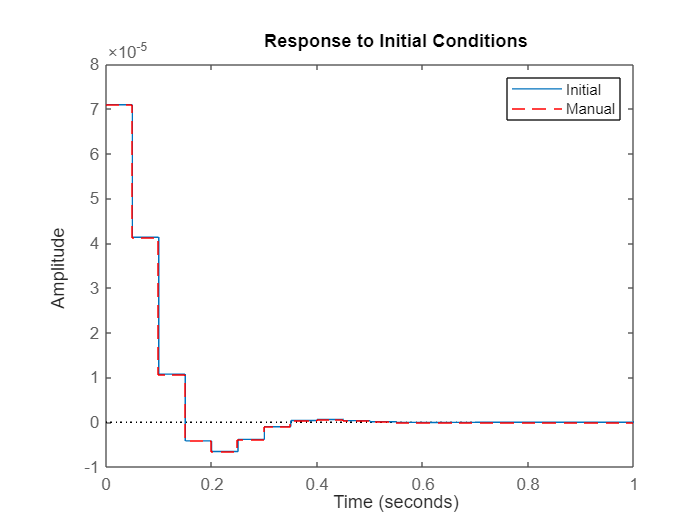

figure;
initial(sys,q0,1);
hold on;
stairs(k_values*Ts, yk, '--r');
legend('Initial', 'Manual');
hold off;

Vemos portanto que a resposta obtida através dos valores calculados manualmente utilizando o método de Cayley-Hamilton, está extremamente próxima a gerada pela função *initial* do matlab, e portanto obtemos um resultado satisfatório.